**0. Preparation**

clear, close all,clc

    Read raw source data

ans =       192645           1

ans =       192645           1

ans =       192645           1

ans =       192645           1

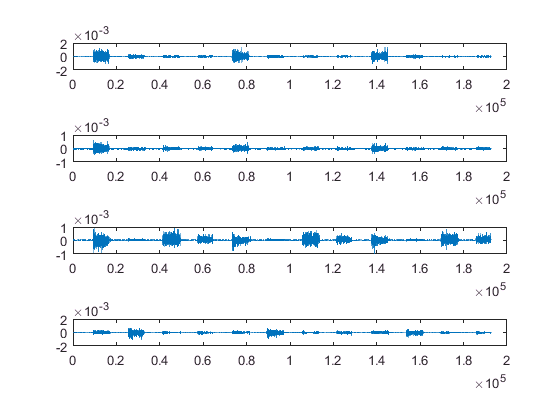

for ch=1:4
    sEMG_raw{ch} = load(['Channel', num2str(ch), '.txt']);
    % source data preview
    subplot(4,1,ch);
    plot(sEMG_raw{ch});
    size(sEMG_raw{ch})
end

**1. 2-order differential filter**

    
$$x_t = y_{t+2} - y_{t+1} - (y_t - y_{t-1})
$$


   
$$x_t = y_{t+2} - y_{t+1} - y_t + y_{t-1}$$


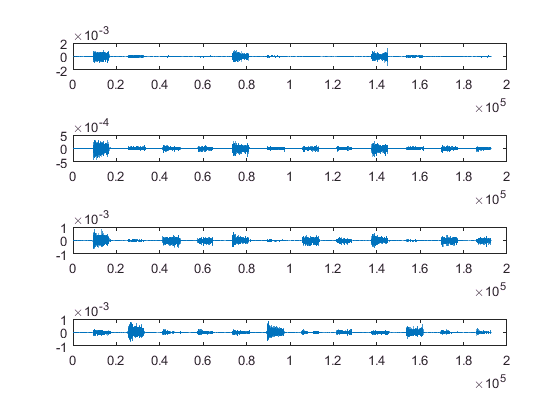

sEMG_2ndFilter = {[], [], [], []};
L = length(sEMG_raw{1});
for ch=1:4
    rd = sEMG_raw{ch};
    for k=2:L-2
        sEMG_2ndFilter{ch} = [sEMG_2ndFilter{ch}; ...
                              rd(k+2)-rd(k+1)-rd(k)+rd(k-1)];      
    end
    clear rd;
end

% 2-order differential filter Preview
for ch=1:4
    subplot(4,1,ch);
    plot(sEMG_2ndFilter{ch});
end

**2. Threshold value computation**